# Lab 3 IMU Active Data Analyis (~the Macarena)

Below is data analysis for the active data we took as a group using the imu in which I did the macarena

clear
clc

dancebag = rosbag('macarena.bag');

% getting time in seconds from bagfile

bSel = select(dancebag, 'Topic', '/imu');
msgStructs = readMessages(bSel,"DataFormat","struct");
time_secs = double(cellfun(@(m) m.Header.Stamp.Sec,msgStructs));
time_nsecs = double(cellfun(@(m) double(m.Header.Stamp.Nsec),msgStructs));

time = time_secs + (time_nsecs * 10^-9);
time = time - time(1);


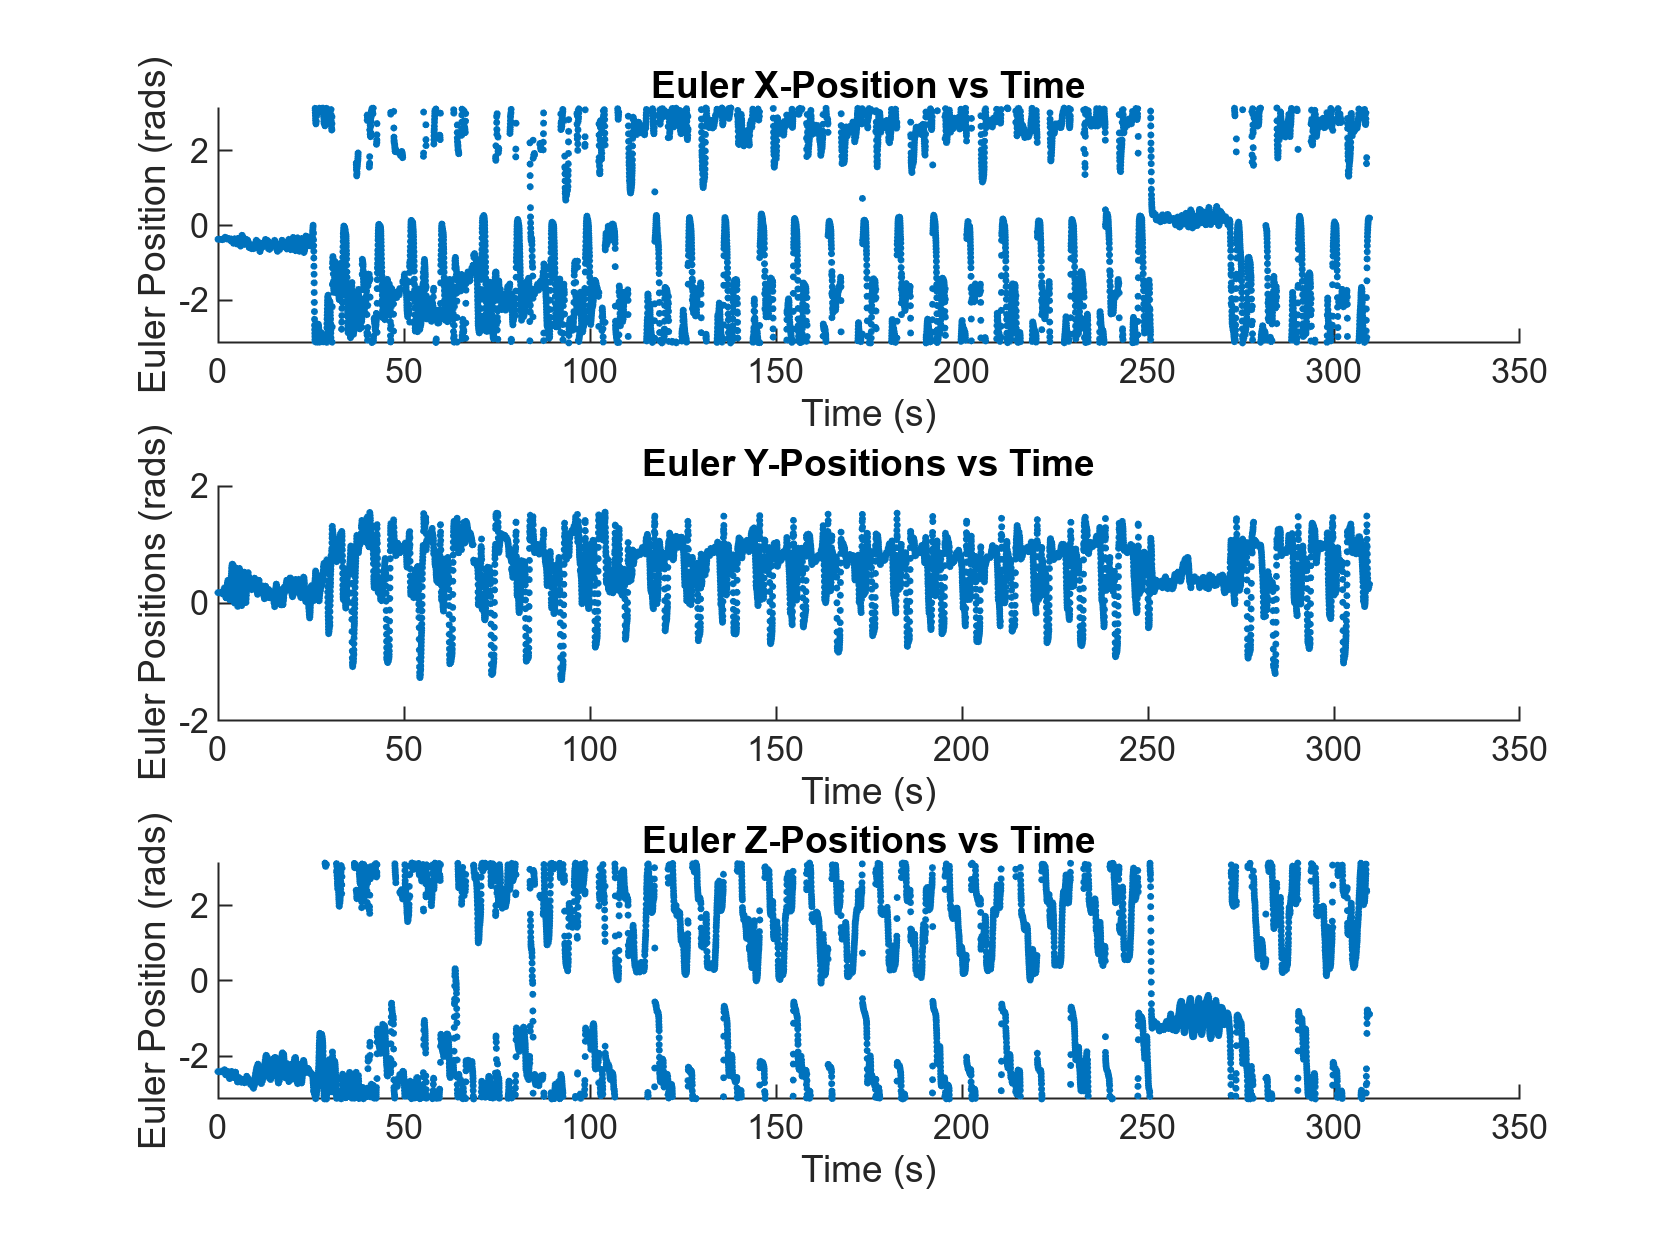

% Getting out the data

% Euler Angle Positions

% getting quaternion positions first (w,x,y,z)
quatpositions= zeros(length(time),4);

quatpositions(:,1) = double(cellfun(@(m) m.Imus.Orientation.W,msgStructs)); % w of quaternion
quatpositions(:,2) = double(cellfun(@(m) m.Imus.Orientation.X,msgStructs)); % x of quaternion
quatpositions(:,3) = double(cellfun(@(m) m.Imus.Orientation.Y,msgStructs)); % y of quaternion
quatpositions(:,4) = double(cellfun(@(m) m.Imus.Orientation.Z,msgStructs)); % z of quaternion

% getting euler angles from quaternion (again, format of quatpositions is
% W,X,Y,Z. Format of eulerpositions after quat2eul is z,y,x but I'm going
% to switch the columns so the eulerpositions format is *Actually* X,Y,Z
% UNIT OF euler angles is radians

eulerpositions = quat2eul(quatpositions);
% switching the columns
dummyColumn = eulerpositions(:,1);
eulerpositions(:,1) = eulerpositions(:,3);
eulerpositions(:,3) = dummyColumn;


% Angular Velocity (format of columns is in X,Y,Z), UNITS are in rad/s
angvels = zeros(length(time),3);
angvels(:,1) = double(cellfun(@(m) m.Imus.AngularVelocity.X,msgStructs));
angvels(:,2) = double(cellfun(@(m) m.Imus.AngularVelocity.Y,msgStructs));
angvels(:,3) = double(cellfun(@(m) m.Imus.AngularVelocity.Z,msgStructs));


% Linear Acceleration

% linaccel is an array containing linear acceleration data. UNITS are in
% m/s^2, the columns 1,2, and 3 are X,Y,Z respectively
linaccel = zeros(length(time),3);
linaccel(:,1) = double(cellfun(@(m) m.Imus.LinearAcceleration.X,msgStructs));
linaccel(:,2) = double(cellfun(@(m) m.Imus.LinearAcceleration.Y,msgStructs));
linaccel(:,3) = double(cellfun(@(m) m.Imus.LinearAcceleration.Z,msgStructs));

% Magnetic Field

% magfield is an array containing the magnetometer data (which measures
% strength and direction of a magnetic field). UNITS are in Teslas
% (converted from Gauss in python driver) and columns 1,2,3 are X,Y,Z
% respectively

magfield = zeros(length(time),3);
magfield(:,1) = double(cellfun(@(m) m.MagField.MagneticField_.X,msgStructs));
magfield(:,2) = double(cellfun(@(m) m.MagField.MagneticField_.Y,msgStructs));
magfield(:,3) = double(cellfun(@(m) m.MagField.MagneticField_.Z,msgStructs));


figure
subplot(3,1,1)
scatter(time,eulerpositions(:,1),'.')
title('Euler X-Position vs Time');
xlabel('Time (s)');
ylabel('Euler Position (rads)');
subplot(3,1,2)
scatter(time,eulerpositions(:,2),'.')
title('Euler Y-Positions vs Time');
xlabel('Time (s)');
ylabel('Euler Positions (rads)');
subplot(3,1,3)
scatter(time,eulerpositions(:,3),'.')
title('Euler Z-Positions vs Time');
xlabel('Time (s)');
ylabel('Euler Position (rads)');

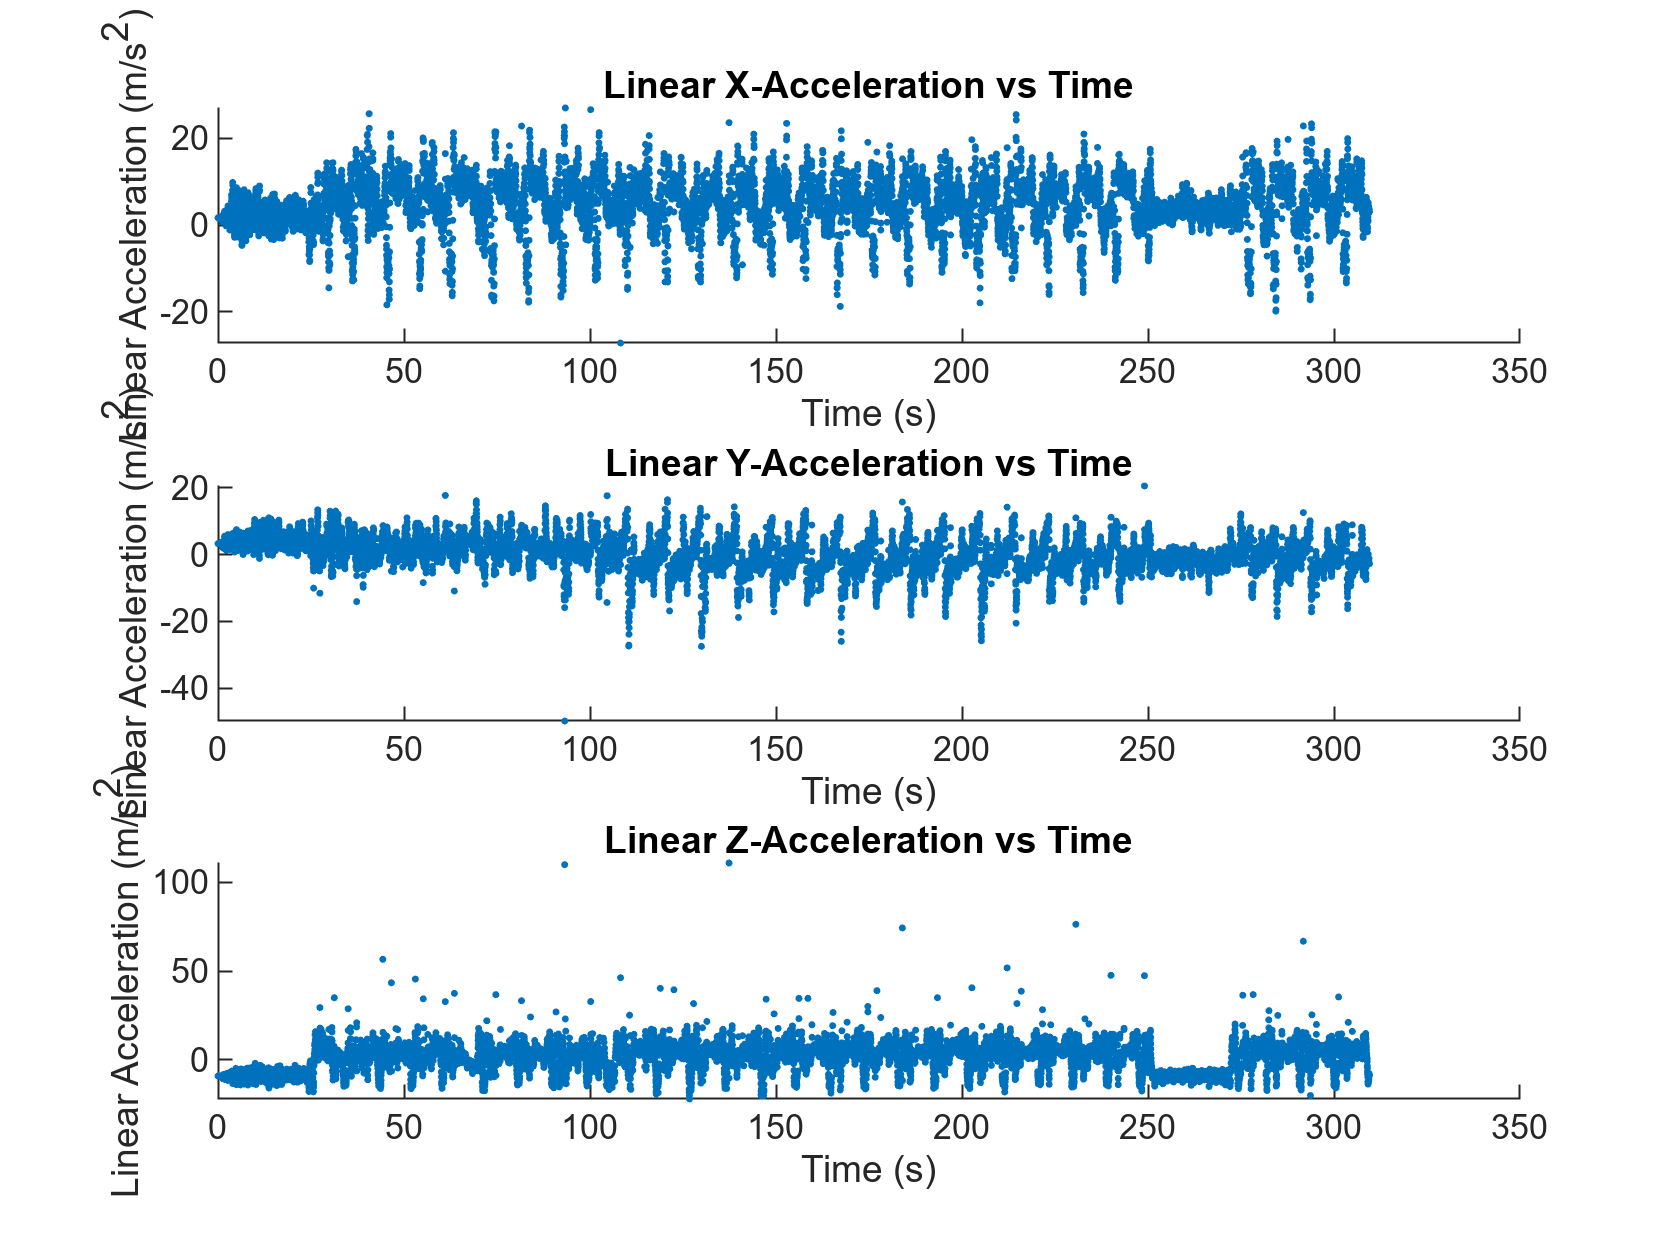



figure
subplot(3,1,1)
scatter(time,linaccel(:,1),'.')
title('Linear X-Acceleration vs Time');
xlabel('Time (s)');
ylabel('Linear Acceleration (m/s^2)');
subplot(3,1,2)
scatter(time,linaccel(:,2),'.')
title('Linear Y-Acceleration vs Time');
xlabel('Time (s)');
ylabel('Linear Acceleration (m/s^2)');
subplot(3,1,3)
scatter(time,linaccel(:,3),'.')
title('Linear Z-Acceleration vs Time');
xlabel('Time (s)');
ylabel('Linear Acceleration (m/s^2)');

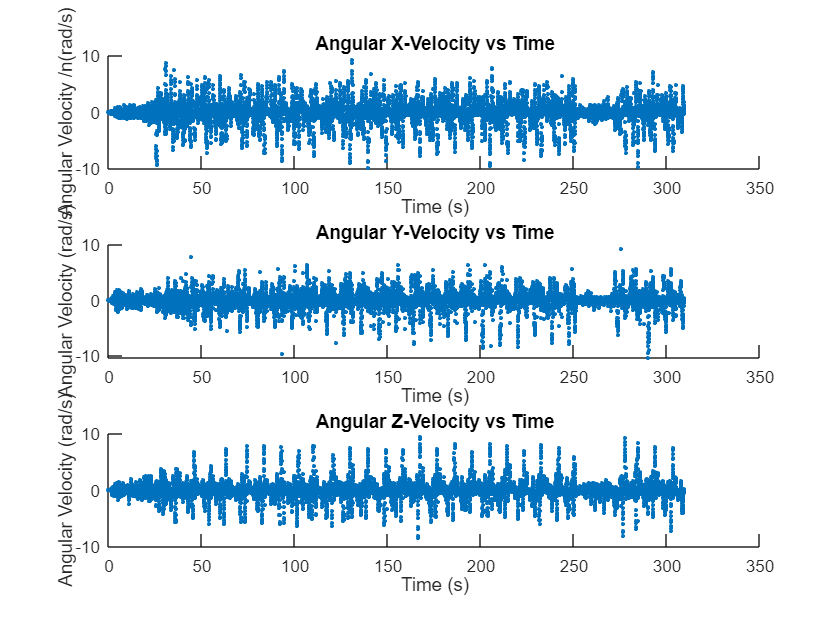



figure
subplot(3,1,1)
scatter(time,angvels(:,1),'.')
title('Angular X-Velocity vs Time');
xlabel('Time (s)');
ylabel('Angular Velocity /n(rad/s)');
subplot(3,1,2)
scatter(time,angvels(:,2),'.')
title('Angular Y-Velocity vs Time');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
subplot(3,1,3)
scatter(time,angvels(:,3),'.')
title('Angular Z-Velocity vs Time');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');

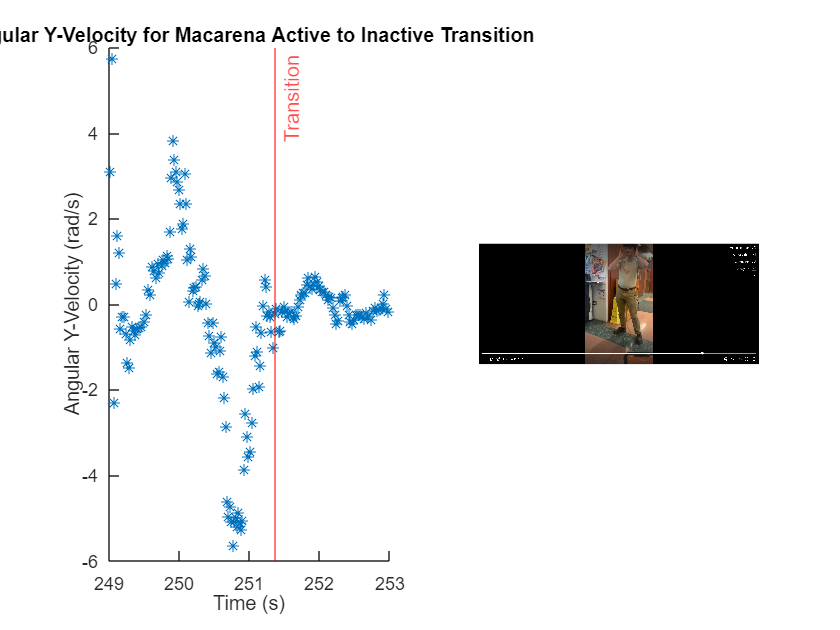



%%%%%%%%%%%%%%%%%%%%%% Plotting three cases from video that line up with
%%%%%%%%%%%%%%%%%%%%%% clips from video.....


% FIRST, the transition from active macarena to "cooldown" at 4:09-4:13 in
% video or seconds 249-254 in data. Behavior is shown via angular velocity
% y
figure
subplot(1,2,1)
scatter(time([9963:10130]),angvels([9963:10130],2),'*')
title('Angular Y-Velocity for Macarena Active to Inactive Transition')
xlabel('Time (s)')
ylabel('Angular Y-Velocity (rad/s)')
xline(251.37,'Label','Transition','Color','red')
subplot(1,2,2)
imshow('BBCase1.png')

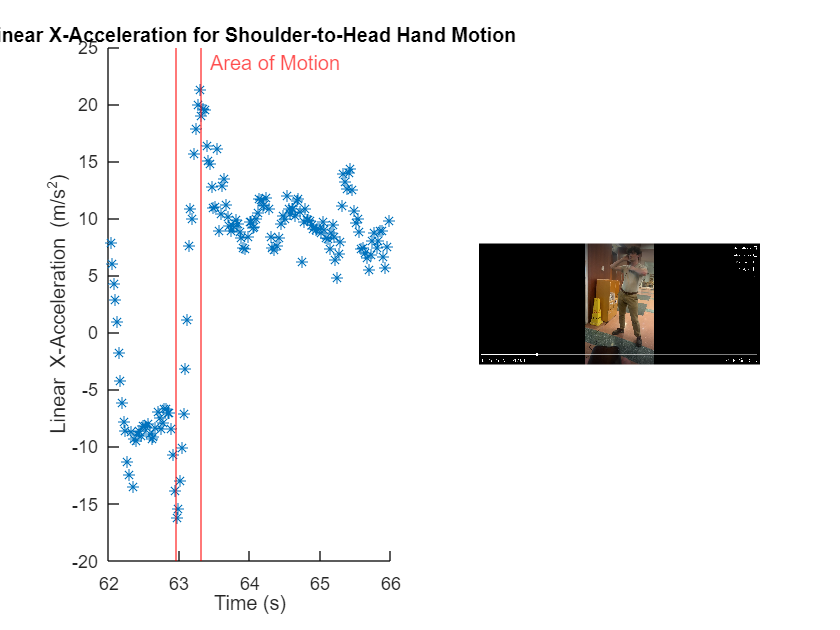







% SECOND, capturing the behavior of the hands going from should to side of head opposite to it during
% the macarena. Occurs at 62.8s in and around the 74s mark too. Will plot 62-64 to capture peak acceleration
% that occurs in linear X acceleration data during movement. One added
% bonus of this is that it is cyclical

figure 
subplot(1,2,1)
scatter(time([2492:2650]),linaccel([2492:2650],1),'*')
title('Linear X-Acceleration for Shoulder-to-Head Hand Motion')
xlabel('Time (s)')
ylabel('Linear X-Acceleration (m/s^2)')
xline(62.96,'Color','red')
xline(63.32,'Label','Area of Motion','Color','red','LabelOrientation','horizontal')
subplot(1,2,2)
imshow('BBCase2.png')

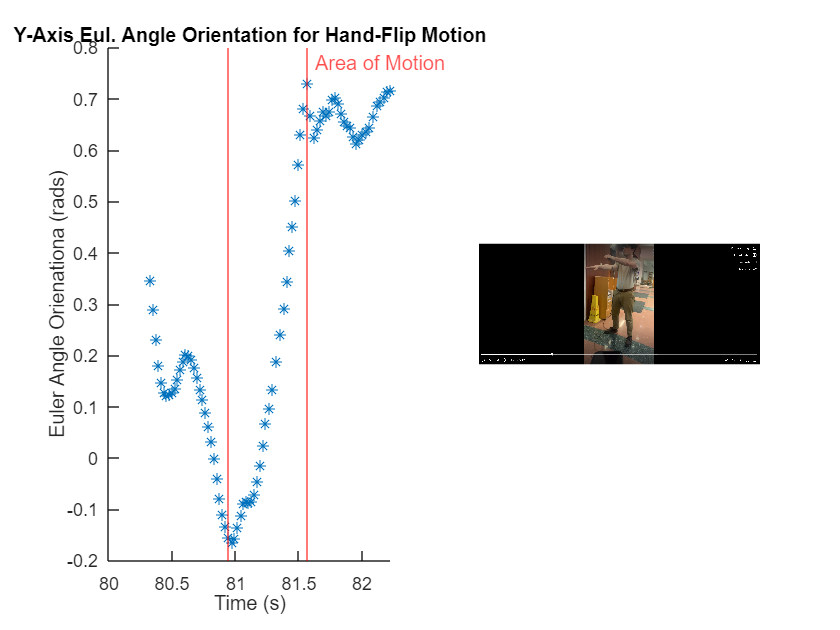





% THIRD, capturing the behavior of the hand flip (when hands are
% outstretched and palms flip to face opposite direction. Evidenced in the
% Y-Euler Angle orientaiton data below between around 81-83 seconds into
% the video.
figure 
subplot(1,2,1)
scatter(time([3220:3300]),eulerpositions([3220:3300],2),'*')
title('Y-Axis Eul. Angle Orientation for Hand-Flip Motion')
xlabel('Time (s)')
ylabel('Euler Angle Orienationa (rads)')
xline(80.945,'Color','red')
xline(81.566,'Label','Area of Motion','Color','red','LabelOrientation','horizontal')
subplot(1,2,2)
imshow('BBCase3.png')